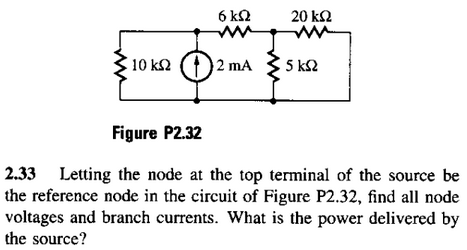

Primero nombramos los nodos con Va como nuestro nodo de referencia

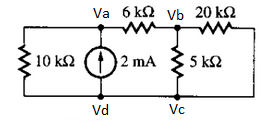

Asumimos que el nodo de referencia Va = 0V y sabemos que los nodos Vd y Vc = 0V, por lo tanto solo tenemos un nodo incognita Vb, para saber la tension en este nodo reducimos las resistencias en paralelo con la fuente

r_eq = 6000 + 1/((1/5000)+(1/20000)) %ohm

r_eq = 10000

Al tener dos resistencias de 10k en paralelo con la fuente de corriente, deducimos que por cada resistor se van **1 mA**, sabiendo esto, devolviendonos al circuito original, sabemos que por el resistor de 6k, para 1mA de corriente, que por ley de ohm V = 6k*1mA = 6V, hay una caida de tension de 6 V en el resistor de 6k, ahora solo queda aplicar un divisor de corriente para saber cuanta corriente pasa por los resistores de 5k y 20k, sabiendo que les entra 1 mA.

ir_5k = 1e-3* 20000/(5000+20000) %amperios

ir_5k = 8.0000e-04

ir_20k = (1e-3)-ir_5k %amperios

ir_20k = 2.0000e-04

Ahora que sabemos la corriente en cada elemento, calculamos la tension en cualquiera de los dos, ya que estan en paralelo:

vr_20k = ir_20k*20000 %voltios

vr_20k = 4.0000

vemos que en el resistor de 20k hay una caida de tension de **4V, que es la misma tension de nodo Vb**

Por ultimo verificamos en el simulador: